# Принцип максимального правдоподобия. Регуляризация при нелинейной оптимизации и метод Левенберга-Марквардта

Сегодня мы, во-первых, уйдем от обычного метода наименьших  квадратов (**O**rdinary **L**east **S**quares) и будем рассматривать более общие модели, как для линейной так и для нелинейной регрессии. Основным способом получения таких моделей является принцип максимального правдоподобия, основная идея которого состоит в том, чтобы найти такую оценку параметров модели,  которая наилучшим образом (с наибольшей вероятностью) предсказывает появляение тех данных, которые наблюдаются в эксперименте.  Кроме того целью будет проследить как работает регуляризация в задачах нелинейной регрессии.

### 1.Функция правдоподобия и принцип максимального правдоподобия

Пусть у нас есть некоторый набор экспериментальных точек в виде вектора $\vec{y}$ с $N$ элементами, которые являются независимыми выборками некоторой случайной величины, то есть все эти точки получены из одного распределения вероятности, характеризуемого набором параметров $\vec{b}$. Тогда вероятность получить наблюдаемый набор точек будет равна произведению вероятностей каждого из исходов ($y_i$) в отдельности:

$\mathcal{P}(\vec{y};\vec{b}) = \prod_{i=1}^Np(y_i ;\vec{b})$                                    (1)

$p(y_i|\vec{b})$ - вероятность получить точку со значением $y_i$ из некоторого распределения, характеризуемого набором параметров $\vec{b}$.

Если рассматривать вероятность как функцию параметров  $\vec{b}$, то она называется функцией правдоподобия.

$\mathcal{L}(\vec{b}|\vec{y}) =\mathcal{P}(\vec{y},\vec{b})$                                          (2)

Основная идея принципа максимального правдоподобия состоит в том чтобы находить такие параметры $\vec{b}$, которые максимизируют вероятность получить набор точек, измеренных в эксперименте:


$$\vec{b}_{MLE} = \mathrm{argmax}(\mathcal{L}(\vec{b}|\vec{y}))$$


MLE - maximum likelihood estimator

#### **Биномиальное распределение:**

$p(y | n, p) = \binom{n}{y} \psi ^y (1-\psi)^{n-y}, \quad y = 0,1,\dots,n$ - используется при анализе дисретных событий с бинарным исходом типа бросания монетки, $\psi$ - вероятность единичного положительного исхода, n - число бросаний.

 Значение плотности вероятности дает вероятность получить $y$ удачных исходов при n розыгрышах.

В качестве параметров  этого распределения будем рассматривать вероятность получения положительного исхода $p$ при единичном бросании. В качестве единичного  исхода $y_i$ будем рассматривать число выпадения "решки" при фиксированном числе бросков $n$. Функция правдоподобия рассчитывается по формулам (1,2).

%
clearvars
p_true =0.42;
N = 80;% число розыгрышей
M = 10;% число  бросаний в каждой точке
data = rand(N,M) < p_true
p =0.41;
bin_fun = @(k) nchoosek(M,k)*(p^k)*(1-p)^(M-k) ;

data = 80×10 logical array
   1   1   0   0   0   1   1   0   0   0
   0   0   1   1   0   1   1   0   1   0
   0   1   0   1   0   1   1   0   0   1
   1   1   0   1   1   0   0   1   1   0
   0   1   0   0   0   0   1   0   0   1
   0   1   0   0   0   0   0   0   1   0
   0   1   0   0   0   0   1   0   0   1
   1   1   0   0   0   1   1   0   1   1
   0   1   1   0   1   0   1   0   1   1
   0   1   1   1   1   0   0   1   1   0


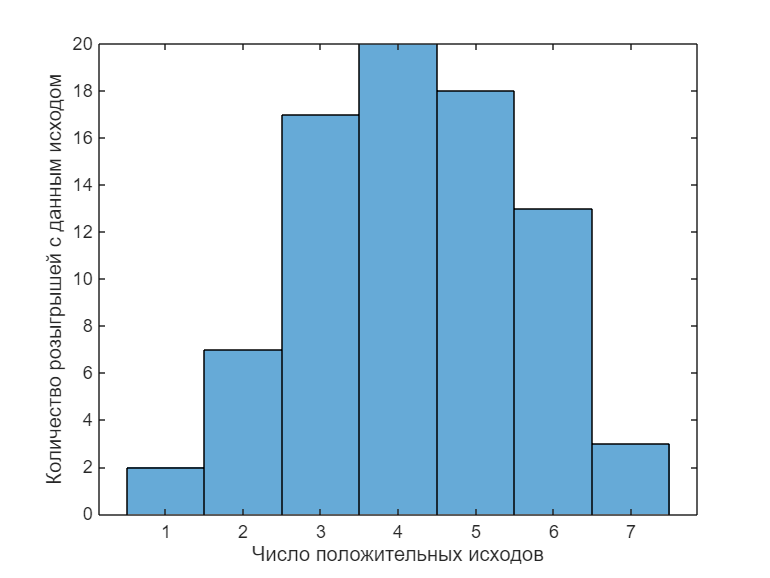

p_i = zeros(N,1);
y_i=  zeros(N,1);
for ii = 1:N
    y_i(ii) = sum(data(ii,:)); % число удачных бросаний в ii-м розыгрыше
    p_i(ii) = bin_fun(y_i(ii));% вероятность данного исхода
end
histogram(y_i)
xlabel("Число положительных исходов")
ylabel("Количество розыгрышей с данным исходом")
L = prod(p_i)


psi = 0:1e-3:1;

L = 3.8483e-62

LikeliHoodFunc = @(d,p) prod(arrayfun(@(k) nchoosek(M,k)*(p^k)*(1-p)^(M-k), sum(d,2)))
Li = arrayfun(@(p_ii)LikeliHoodFunc(data,p_ii),psi)
plot(psi,Li)

LikeliHoodFunc = function_handle with value:
    @(d,p)prod(arrayfun(@(k)nchoosek(M,k)*(p^k)*(1-p)^(M-k),sum(d,2)))


xlabel("Параметр \psi")

Li = 1.0e-61 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


ylabel("Функция правдоподобия, L(\psi)")
hold on
[lmax,indmax] = max(Li)
scatter(psi(indmax),lmax,"*r")
text(psi(indmax),lmax,string(psi(indmax)))

lmax = 4.5385e-62

indmax = 421

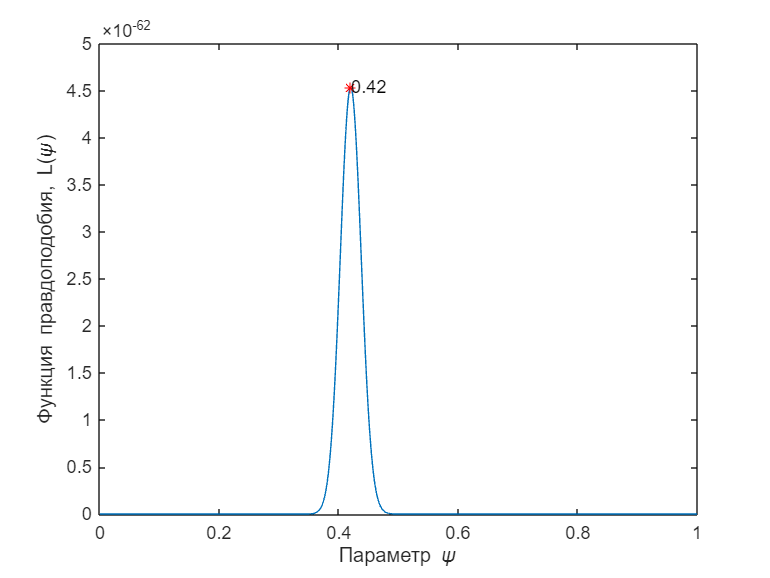

hold off

Максимизируется как правило логарифм функции правдоподобия (loglikelihood):


$$\mathcal{l}(\vec{b}) = log(\mathcal{L})$$


Либо минимизируется $-\mathcal{l}(\vec{b})$

logl_fn = @(p_ii)-log(LikeliHoodFunc(data,p_ii))
plot(psi,arrayfun(logl_fn,psi))
title("loglikelihood")

logl_fn = function_handle with value:
    @(p_ii)-log(LikeliHoodFunc(data,p_ii))


Одномерная оптимизация с ограничениями, чтобы найти параметр распределения

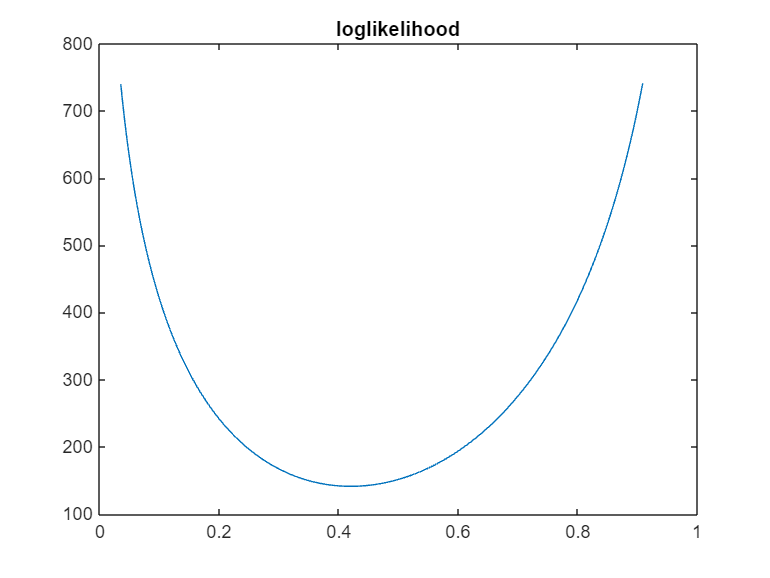

ans = 0.4200

fminbnd(logl_fn,0,1)

#### Распределение Пуассона:

Как уже упоминалось, принцип максимального правдоподобия может исопльзоваться и для другой других функций распределения.

Распределение Пуассона:

$p(y | \lambda) = \frac{\lambda^y e^{-\lambda}}{y!}, \quad y = 0,1,2,\dots$ дает вероятность получения y редких событий, где параметр $\lambda$ - это среднее число событий. Например, если производится наблюдение за некоторым процессом во времени, то $\lambda$ будет средним числом событий за весь интервал времени, а y - это конкретное число событий.  

Предполаем события (измерения)  независимыми, соотвественно для формулировки функции правдоподобия мы можем пользоваться формулой.

Вектор экспериментальных данных $\vec{y}$, мы предполагаем, что каждая точка получена из распределения Пуассона со своим средним значением $\lambda_i$, так как мы хотим несмещенную оценку, наша модель должна, соотвественно, быть равна среднему значению для каждой из точек $f(\vec{b})_i = \lambda_i$. Функция правдоподобия:


$$\mathcal{L}(\vec{b}|\vec{y}) = \prod_i \frac{(f_i)^{y_i} e^{-f_i}}{y!}$$


loglikelihood:


$$\mathcal{l}(\vec{b}|\vec{y}) = \mathrm{log}(\prod_i \frac{(f_i)^{y_i} e^{-f_i}}{y_i!})= \sum_i[y_ilog(f_i) - log(y_i!)  - f_i] $$


Распределение Пуассона применяется для анализа редких событий, таких, как, например, возникновение брака в технологическом цикле. Имея, например, статистику разрушений изделий, можно построить модель для анализа тренда на уменьшение или увеличение количества брака.

ans = 30×1 table
    y
    _

    1
    5
    6
    5
    8
    3
    2
    3
    2
    5
    2
    4
    2
    5
    6
    4


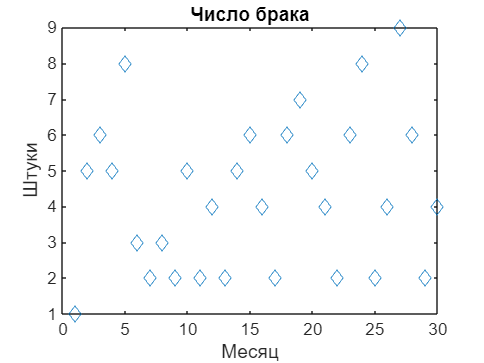

clearvars
N = 30; % длительность наблюдения 
l0 = 4;
l1 = 1/N;
l2 = -5e-3/N;
l_true = [l2,l1,l0];
x = transpose(1:N);
lambda_true = polyval(l_true,x);% истинное изменение среднего значения от месяца к месяцу
y = arrayfun(@(lami)poissrnd(lami,1,1),lambda_true(:)); % вектор экспериментальных данных - число брака за 50 месяцев
table(y) % таблица количества брака в месяц
plot(x,y,"diamond");title("Число брака");xlabel("Месяц");ylabel("Штуки");
histogram(y);title("Число бракованных изделий");ylabel("Частота");xlabel("Число брака")

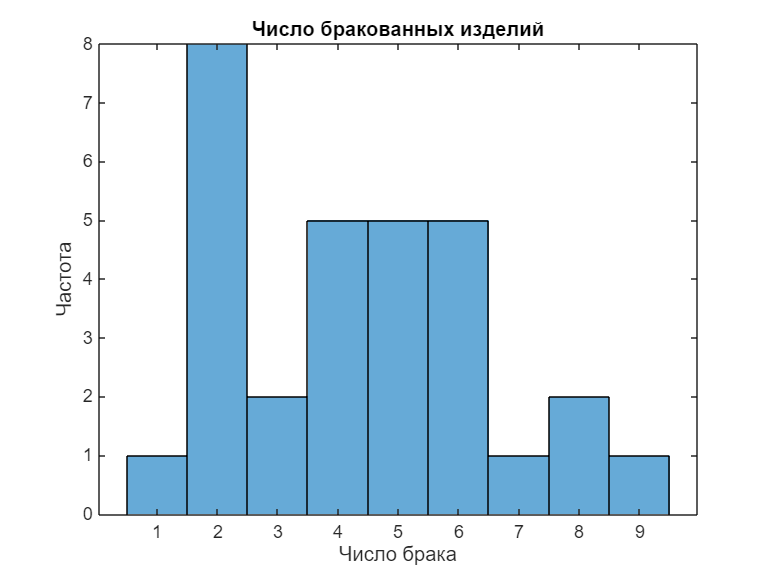

poisson_quality = 0;

polyfit_quality = 0;
pp_mean= 0;
pf_mean = 0;
trials_number = 5
for ii = 1:trials_number
    y = arrayfun(@(lami)poissrnd(lami,1,1),lambda_true(:));

trials_number = 5

    f_average = @(p) polyval(p,x);
    logl_fn = @(p) -sum(y.*log(f_average(p)) - log(gamma(y + 1)) - f_average(p)); % вместо факториала используем
% Гамма функцию, которая распространяет понятие факториала на все
% действительные числа
    poisson_regression = fminsearch(logl_fn,[1e-3,1e-2,3]); % решение задачи оптимизации
    polynomial_fit = polyfit(x,y,2); % обычный фитинг полиномом
    pp_mean = pp_mean + poisson_regression;
    pf_mean = pf_mean + polynomial_fit;
    poisson_quality = poisson_quality + norm(poisson_regression - l_true)/norm(l_true);
    polyfit_quality = polyfit_quality + norm(polynomial_fit - l_true)/norm(l_true);
end
poisson_regression = pp_mean/trials_number
polynomial_fit= pf_mean/trials_number
l_true

poisson_regression =     0.0003    0.0193    3.9170


polynomial_fit =     0.0008    0.0072    3.9738


 poisson_quality= poisson_quality/trials_number

l_true =    -0.0002    0.0333    4.0000


polyfit_quality= polyfit_quality/trials_number


poisson_quality = 0.3039

plot(x,lambda_true);

polyfit_quality = 0.3024

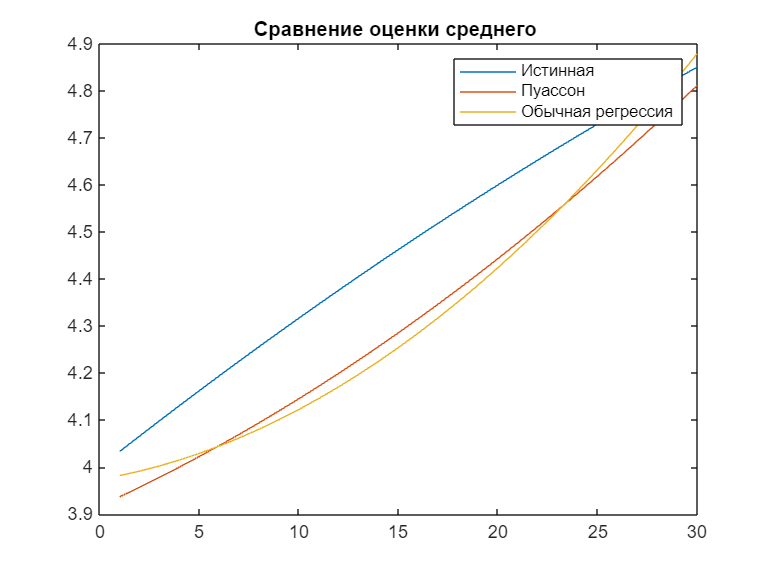

hold on 
plot(x,f_average(poisson_regression));
plot(x,polyval(polynomial_fit,x));
hold off
legend(["Истинная","Пуассон", "Обычная регрессия"])
title("Сравнение оценки среднего ")


### 2.Принцип максимального правдоподобия для решения задач регрессии при Гауссовой ошибке

У нас есть некоторая модель $f(\vec{\beta},\vec{x})$, которая зависит от набора параметров $\vec{\beta}$ и независимых переменных $\vec{x}$ . В задачах оптимизации, мы хотим найти оценку $\vec{b}$ истинных параметров модели $\vec{\beta}$ по измеренным данным  $\vec{y}$. Сама модель полагается верной и детерминированной, то есть, все отклонения измеренных данных от модели имеют случайную природу. Такми образом, можно сказать, что ошибка для каждого отдельного измерения получена из некоторого распределения.

Вопрос пригодности модели $f(\vec{\beta},\vec{x})$ для описания какого-то явления или процесса может быть изучен после решения задачи регрессии путем анализа справедливости исходного предположения регрессии - случайности ошибки регрессии. 

Пусть ошибка имеет нормальное распределение:

$ \mathcal{N}(0,1)$ - стандартное нормальное распределение (функция randn)

Чтобы получить переменную, взятую из $\zeta \sim \mathcal{N}(\mu,\sigma^2)$ из переменной, взятой из стандартного распределения $ \eta \sim \mathcal{N}(0,1)$


$$\zeta \sim \mathcal{N}(\mu,\sigma^2) = \mu + \sigma^2  \eta$$


Ошибка  равна разнице экспериментальных данных и предсказания модели для $i$ -й точки:


$$e_i= y_i - f(\vec{b})_i$$


Если ошибка берется из несмещеннjuj распределения (  $\mathcal{N}(0, \sigma^2)$ ), то для отдельного измерения: 


$$p(e_i) \propto p_0\exp\left( -\frac{1}{2} \frac{(y_i - f_i)^2}{\sigma^2} \right)$$


Это эквивалентно тому, что $y_i \sim \mathcal{N}(f_i,\sigma)$, то есть, сами точки получены из нормального распределения со средним значением $f_i$

Предполагая, что ошибки не зависят друго от друга, согласно формуле (1) для loglikelihood:


$$\mathcal{l}(\vec{b}) = \mathrm{log}(\mathcal{L})= \mathrm{log}( \prod_i^Np_0\exp\left( -\frac{1}{2} \frac{(y_i - f_i)^2}{\sigma^2} \right) = C  - \frac{1}{2\sigma^2} \sum_i^N (y_i - f_i)^2 = C-  \frac{1}{2}(\vec{y} - \vec{f})^T(\vec{y} - \vec{f})$$


При условии, что $\sigma^2$ постоянна для всех точек, мы получим обыкновенный метод наименьших квадратов (ordinary least squares).

Выражение для вероятности конкретного значения можно было бы переписать так:


$$\vec{y} \sim \mathcal{N}(\vec{f},\sigma I)$$


Прицип максимального правдоподобия может быть использован для оценки параметров модели даже если ошибка получена из  многомерного распределения Гаусса $\vec{y} \sim \mathcal{N}(\vec{\mu}, \Sigma)$, где:


$$\[
\mathcal{N}(\vec{y} \mid \vec{\mu}, \Sigma) = \frac{1}{(2\pi)^{\frac{d}{2}} |\Sigma|^{\frac{1}{2}}} \exp \left( 
-\frac{1}{2} (\vec{y} - \vec{\mu})^T \Sigma^{-1} (\vec{y} - \vec{\mu}) 
\right)
\]$$


Здесь $d$   - число измерений, $\Sigma$ - матрца ковариации размером (dxd), $\vec{\mu}$ - вектор средних значений по каждой из координат, $|\Sigma|$ - определитель матрицы ковариации.

MVG2 = @(x,mu,Sigma) exp(-(x(:)-mu(:))'*(Sigma\(x(:)-mu(:)))/2)/(2*pi*sqrt(det(Sigma))) % двумерное нормальное распредение
Sigma = [3,1;...
         1,2]

MVG2 = function_handle with value:
    @(x,mu,Sigma)exp(-(x(:)-mu(:))'*(Sigma\(x(:)-mu(:)))/2)/(2*pi*sqrt(det(Sigma)))


mu = [0;0]
try 

Sigma =      3     1
     1     2


    det(Sigma);

mu =      0
     0


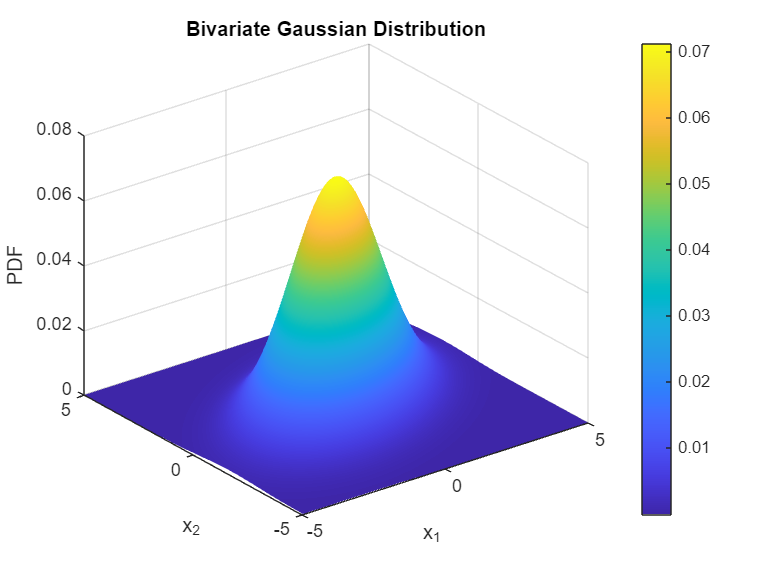

    chol(Sigma);
catch ex
    disp(ex.message)
    disp("not positive defifnite")
    return
end
% Create grid for evaluation
x1 = -5:0.1:5;
x2 = -5:0.1:5;
[X1, X2] = meshgrid(x1, x2);
X = [X1(:), X2(:)];              %
Ngrid = size(X,1);
y = zeros(Ngrid,1);
for ii = 1:Ngrid
    y(ii) = MVG2(X(ii,:),mu,Sigma);
end
y = reshape(y, length(x2), length(x1));
surf(X1, X2, y);
xlabel('x_1'); ylabel('x_2'); zlabel('PDF');
title('Bivariate Gaussian Distribution');
colorbar; shading interp;
[u,s] = eig(Sigma)
u'*u

s = diag(s);

u =     0.5257   -0.8507
   -0.8507   -0.5257


s =     1.3820         0
         0    3.6180


ax = get_next_ax()

ans =     1.0000         0
         0    1.0000


contour(ax,X1,X2,y)
hold(ax,"on");

fig11


ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


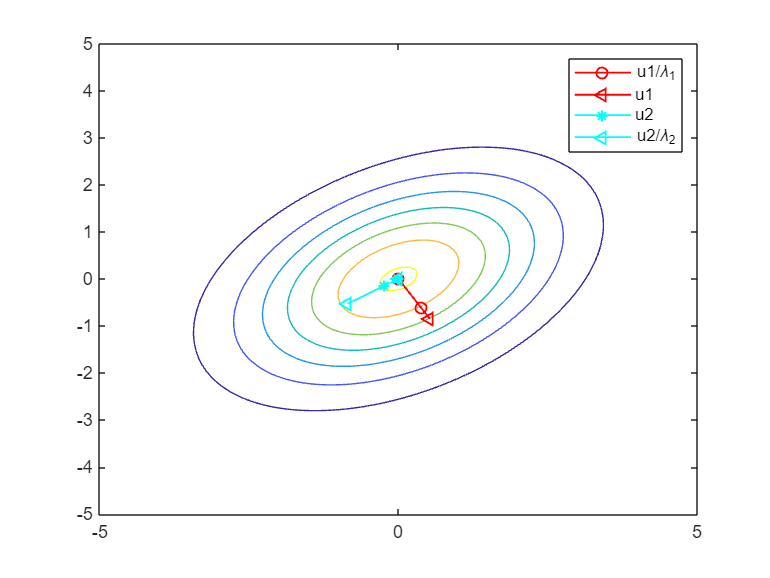

plot(ax,[mu(1);u(1,1)/s(1)],[mu(2),u(2,1)/s(1)],"Marker","o","Color","red","LineWidth",1)
plot(ax,[mu(1);u(1,1)],[mu(2),u(2,1)],"Marker","<","Color","red","LineWidth",1)
plot(ax,[mu(1);u(1,2)/s(2)],[mu(2),u(2,2)/s(2)],"Marker","*","Color","cyan","LineWidth",1)
plot(ax,[mu(1);u(1,2)],[mu(2),u(2,2)],"Marker","<","Color","cyan","LineWidth",1)
hold(ax,"off")
legend(ax,["","u1/\lambda_1","u1","u2","u2/\lambda_2" ])

В матлабе есть встроенная функция которая позволяет генерировать случаные вектора из гауссова распределения :

 mvnrnd(mu, Sigma) - первый аргумент - вектор средних, Sigma - матрица ковариации распределения

Помимо Гауссова, существует еще несколько распрделений, которые имеют подобную компактную форму для коррелированных данных, но для случая произвольного распределения получить такое простое выражение не удается.

#### Функция правдоподобия для коррелированной гаусовой ошибки:

$\mathcal{L}(\vec{b}|\vec{y})  \propto \mathrm{exp}(-\frac{1}{2}(\vec{f_b} -\vec{y})^T \Sigma^{-1}(\vec{f_b} - \vec{y}))$                                         (3)

$\Sigma$ - матрица ковариации входных данных, формула остается справедливой для коррелированных данных!

#### **Геометрия расстояния Махаланобиса**

Конструкцию, которая стоит в показатели экспоненты  называют *Mahalanobis distance*, она имеет смысл расстояния между двуия векторами $\vec{f_b}$ и $\vec{y}$.

Если вспомнить, что матрица ковариации является симметричной положительно-определенной, то матрицы ее собственных векторов являются ортонормированными,  спектральное разложение этой будет иметь вид: $\Sigma = U\Lambda U^T = \sum_d \lambda_d\vec{u}_d\vec{u}_d^T$ , где  $\vec{u}_d$ - собственные вектора матрицы ковариации , это единичные вектора показывающие направление главных осей информационной матрицы, тогда расстояние Махаланобиса между двумя векторами это:


$$\Sigma^{-1}  = \sum_d \frac{1} {\lambda_d}\vec{u}_d\vec{u}_d^T$$


Чем меньше $\lambda$ - большая вариация в данном направлении!


$$\vec{r}^T\Sigma^{-1}\vec{r} = \sum_d \frac{1}{\lambda_d}[\vec{r}^T\vec{u}_d][\vec{u}_d^T\vec{r}] = \sum_d \frac{z_d^2}{\lambda_d}$$


Вектора $\vec{u}_d$ - единичные вектора, следовательно

$z_d = \vec{r}^T\vec{u}_d$ - это длина проекции вектора разницы на главную ось эллипса.

t = table([[u(:,1),u(:,2)];[norm(u(:,1)),norm(u(:,1))];s']);
t.Properties.RowNames = string({'u(1)','u(2)','||u||','lambda'})

t = 4×1 table
                      Var1        
              ____________________

    u(1)       0.52573    -0.85065
    u(2)      -0.85065    -0.52573
    ||u||            1           1
    lambda       1.382       3.618


При решении обратных задач нестационарного теплопереноса, в качестве измеренных данных, выступают зависимости температур от времени, измеренный при нагреве образца, а в качестве параметров модели,  для коэффициентной ОЗ могут выступать, например, коэффициенты полиномиальной аппроксимации физических свойств материала (теплопроводности, теплоемкости), для граничной ОЗ коэффициенты аппроксимации теплового потока и т.п. 

Модель  $f(\vec{\beta},\vec{x})$ включает в себя, также решение прямой задачи - дифференциального уравнения в частных производных (в простейшем случае одномерного нестационарного) способ решения УЧП также имеет ряд параметров, таких как, например, дисретность сетки по времени и координате, которые в задаче регрессии напрямую не фигурируют, однако эти "скрытые" параметры также могут быть включены в задачу оптимизации.

#### Откуда берут матрицу ковариации в методе нелинейной регрессии?

Для нахождения матрицы $\Sigma$ используется априрорная инормация об ошибке исходных данных. Причем она  не обязана быть строгой матрицей ковариации, так как, в задаче регрессии $\Sigma$ это, в конечном счете, некоторый набор весов, который характеризует вклад отдельных точек ошибки в результирующую невязку.

**Эмпирическим  путем.**

Допустим, в качестве входных данных для ОЗ выступают термопарные измерения, полученные в ходе эксперимента. Например, зависимости температур от времени в нескольких точках образца $\vec{T}_k = T(x_k,t)$ - вектор из $M$ элементов . В этом случае  можно провести серию нагревов в одних и тех же (с экспериментальной точки зрения) условиях.Фактически в качестве оценки может быть использована воспроизводимость результатов измерений. Проведя $N$ измерений, получим матрицу $\Theta_k= [\vec{T^1} - <\vec{T}>,\dots,\vec{T^N} - <\vec{T}>]$, где  $<\vec{T}>$ - вектор усредненной по серии нагревов зависимости температуры от времени (вектор из $K$ элементов). Тогда матрицу ковариации можно оценить как:


$$\Sigma = \Theta_k\Theta_k^T/(N-1)$$


clearvars 
type = "diagonal"
M = 30;
N = 200;

type = "diagonal"

if type=="diagonal"
    true_Sigma = diag(M:-1:1);
else
    [i, j] = meshgrid(1:M, 1:M);
    true_Sigma =30*exp(- abs(i - j)/10)
end
Ttrue = transpose(M*(1:M)); % средняя температура (истинная)
Thetta = zeros(M,N);
for ii = 1:N
    Thetta(:,ii) = Ttrue + mvnrnd(0*Ttrue, true_Sigma)';
end
Tavrgs_sample = mean(Thetta,2);
Thetta = Thetta - Tavrgs_sample;
Sigma_sample = Thetta*Thetta'/(N-1)
norm(true_Sigma - Sigma_sample)/norm(true_Sigma)
norm(true_Sigma)

Sigma_sample =    30.6788   -1.7451    0.8334    2.7597    0.1839   -0.5264    0.9424   -0.2643   -0.6768   -2.6814   -1.1287    0.9764    0.4252   -0.0620    0.9524    0.8382    1.8523    0.2721    4.8534    0.1400    1.7319   -0.1355    0.6793    1.2005   -0.0517   -0.1571    0.0463    0.9443   -0.6548   -0.1672
   -1.7451   34.1801    1.8574   -1.6670    0.8635   -1.0289   -0.0979    0.0717    2.5959    0.4184   -0.0710    0.0059   -1.1969   -0.7766    0.0561   -0.0877   -1.4296    0.1854   -0.0469   -0.1813    2.5344   -0.6243   -0.0169   -1.2644   -0.0603    0.4029    0.3462   -0.6074    0.7669   -0.5231
    0.8334    1.8574   29.4507    2.0622   -1.6629   -4.2641   -0.4744   -0.8691    2.4640   -1.3621    0.9428   -0.3532   -1.2492   -2.2339    1.3422   -1.2752    0.8928   -1.3928   -1.1698   -0.6417    0.4910   -0.7033   -0.5974    1.3999   -1.1396   -1.4020   -0.1710   -1.5504   -0.6498   -0.2621
    2.7597   -1.6670    2.0622   23.9765    4.5717   -1.2309   -0.2124    3.4407  

surf(true_Sigma);title("True covariance")

ans = 0.4376

ans = 30

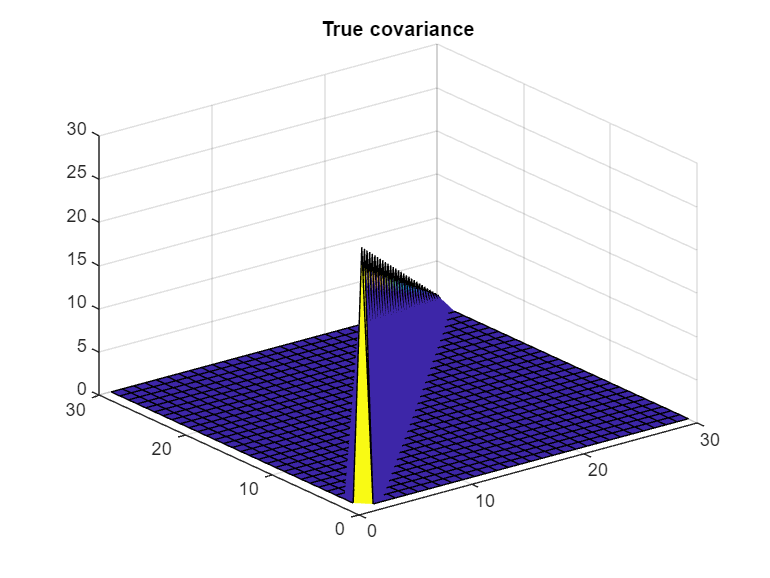

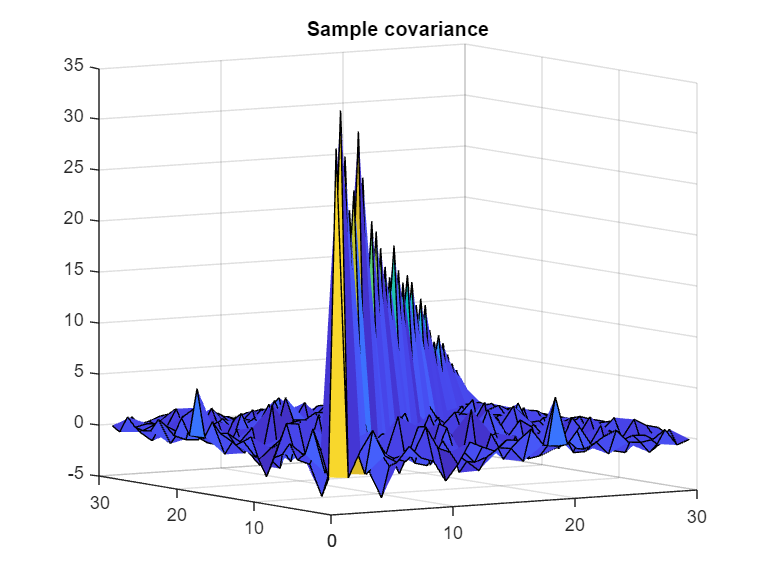

surf(Sigma_sample); title("Sample covariance")

**Погрешность прибора.**

Например, для термопарных измерений, в качестве матрицы могут быть взяты погрешности термопарных измерений

Классы точности по ГОСТ Р 8.585-2001:

Для термопар типа S (ТПП, платина — 10% родий/платина) ГОСТ Р 8.585-2001 устанавливает два класса допуска: класс 1 (повышенная точность) и класс 2 (стандартный).

Погрешности для класса 1

- От 0 до 1100°C: ±1,0°C.

- От 1100 до 1600°C: ±[1,0 + 0,003(t - 1100)]°C, где t — температура в °C.

Погрешности для класса 2

- От 0 до 600°C: ±1,5°C.

- От 600 до 1600°C: ±0,0025t °C, где t — температура в °C.

Эти пределы представляют максимальную погрешность; для моделирования в ковариационной матрице можно использовать  $\sigma \approx \frac{\zeta}{3}$. 

**Эмпирические "предположени".**

Часто предполагают, что вариация прямо пропорциональна самому значению, тогда $\sigma = \psi T$, где $\psi$ это, например, 1е-2, тогда:


$$\Sigma = \psi\mathrm{diag}(\vec{T}^2) $$


**Данные с прибора, получаемые с прибора с конечным временем релаксации **$\tau$**.**

 Ясно, что если частота семплирования меньше времени релаксации, соседние точки по времени будут связаны друг с другом. Для определенности предположим, что речь идет об измерении температуры в зависимости от времени, термопара вместе имеет какое-то конечное время прогрева, а частота оцифровки сигнала с термопары может быть больше этого времени. Ошибка измерения складывается из двух составляющих, случайной ошибки ($e_i$) и ошибки "корреляции":


$$y_i = \vec{a}^T[\matrix{ y_1 \cr \vdots \cr y_{i-1}}] + e_i$$


Коэффициенты $\vec{a}$ корреляционной ошибки не должны зависеть от индеса вектора $\vec{y}$ (то есть от времени), а долны определяться толко некоторым интервалом времени, предшествующим точке $y_i$

 Тогда ковариация может быть представлена в виде функции с релаксацией:


$$\Sigma_{ij} = \sigma^2 \mathrm{exp}( - \frac{|t_i - t_j|}{\tau})=\sigma^2 \mathrm{exp}( - \frac{dt|i - j|}{\tau})$$


Такого вида матрицы, которые зависят от разницы индексов называются матрицами Тёплица, они имеют постоянные элементы на главной и побочной диагоналях (элементы -N и +N диагоналей не обязаны быть одинаковыми, то есть, квадратная матрица Тёплица не обязательно симметрична).

#### Пример. Линейная регрессия для данных коррелированных во времени.

Ошибка берется из гаусоова распределения с матрицей ковариации, соответсвующей коррелированным данным. И сравнивается взвешенная регрессия и обыкновенный метод наименьших квадратов.

clearvars
sigma2 = 0.01; % variance
tau = 3.89; % relaxation time
dt = 0.1; % sampling time < tau
N = 100; % number of samples
% toeplitz
Fs = 1/dt;
ff = Fs/N*(-N/2:N/2-1);
num_trials = 10;
t = (0:N-1)*dt;
[i, j] = meshgrid(1:N, 1:N);
Sigma = sigma2 * exp(- dt*abs(i - j)/tau) % 
V = [ones(N,1), t'];%, t'.^2,t'.^3];

Sigma =     0.0100    0.0097    0.0095    0.0093    0.0090    0.0088    0.0086    0.0084    0.0081    0.0079    0.0077    0.0075    0.0073    0.0072    0.0070    0.0068    0.0066    0.0065    0.0063    0.0061    0.0060    0.0058    0.0057    0.0055    0.0054    0.0053    0.0051    0.0050    0.0049    0.0047    0.0046    0.0045    0.0044    0.0043    0.0042    0.0041    0.0040    0.0039    0.0038    0.0037    0.0036    0.0035    0.0034    0.0033    0.0032    0.0031    0.0031    0.0030    0.0029    0.0028
    0.0097    0.0100    0.0097    0.0095    0.0093    0.0090    0.0088    0.0086    0.0084    0.0081    0.0079    0.0077    0.0075    0.0073    0.0072    0.0070    0.0068    0.0066    0.0065    0.0063    0.0061    0.0060    0.0058    0.0057    0.0055    0.0054    0.0053    0.0051    0.0050    0.0049    0.0047    0.0046    0.0045    0.0044    0.0043    0.0042    0.0041    0.0040    0.0039    0.0038    0.0037    0.0036    0.0035    0.0034    0.0033    0.0032    0.0031    0.0031    0.0030 

p_true = [0.2, -1.4e-2]';%,0.14e-3,-0.14e-6]';
f_true = V*p_true;
cond(Sigma)
r_mse_weighted = 0;

ans = 3.9446e+03

r_mse_unweighted = 0;
for iii = 1:num_trials % чтобы увидеть эффект прогоним регрессию несоклько раз, так как для одного разад эффекта может и не быть
    y = f_true+ mvnrnd(0*f_true, Sigma)';  % Fixed transpose

    % weighted
    p_weighted = (V'* (Sigma \ V)) \ (V' * (Sigma \ y));

    % unweighted 
    p_unweighted = (V'*V) \ (V'*y);
    r_mse_weighted = r_mse_weighted + norm(p_weighted - p_true) / norm(p_true);
    r_mse_unweighted = r_mse_unweighted + norm(p_unweighted - p_true) / norm(p_true);
end
disp("Average RMSE:")
disp("Weighted =" + r_mse_weighted/num_trials);

Average RMSE:


disp("Unweighted =" + r_mse_unweighted/num_trials);

Weighted =0.35527


Unweighted =0.47107


ax = get_next_ax();
scatter(ax,t',y)

fig22


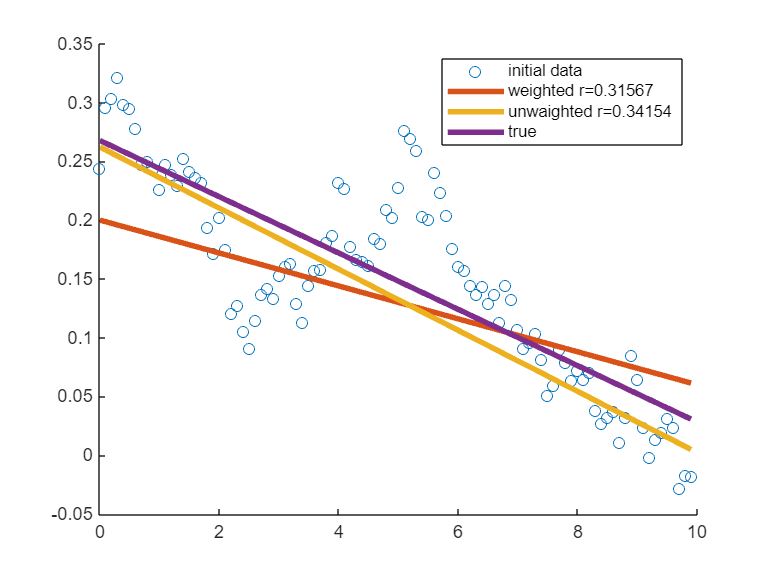

hold(ax,"on");
plot(ax,t',V*p_true,"LineWidth",3);
plot(ax,t',V*p_weighted,"LineWidth",3);
plot(ax,t',V*p_unweighted,"LineWidth",3); 
hold(ax,"off")
legend(ax,["initial data", "weighted r="+ norm(p_true - p_weighted)/norm(p_true), ...
    "unwaighted r="+ norm(p_true - p_unweighted)/norm(p_true),"true"])
t = table(p_true,p_weighted,p_unweighted)

%,"ColumnNames",{'initial data', 'weighted','unwaighted'})

t = 2×3 table
    p_true    p_weighted    p_unweighted
    ______    __________    ____________

       0.2      0.26214        0.26775  
    -0.014    -0.025981      -0.023943  


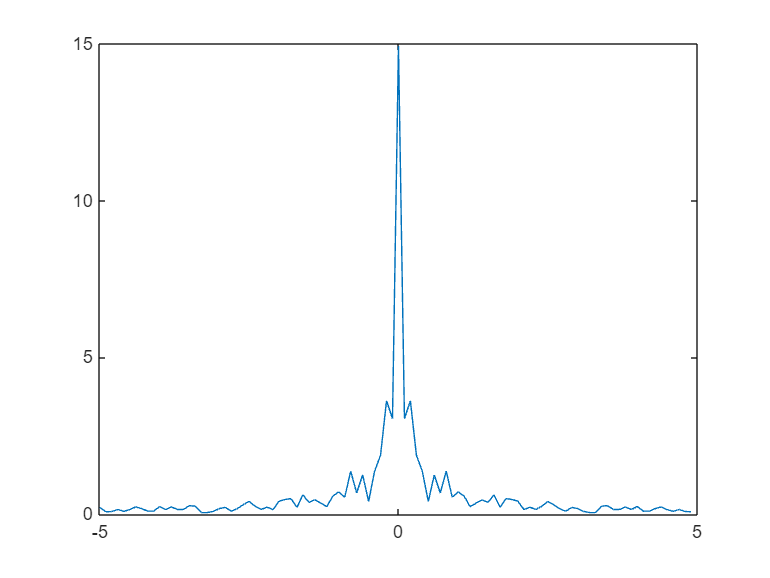

% covariance from fft
fft_y = abs(fftshift(fft(y)));
plot(ff,fft_y)

Видно, что, в среднем взвешенная регрессия выдает меньшую относительную ошибку оценки истинных значенйи параметров (хотя визуально так не скажешь)

При условии, что измерения независимы друг от друга, матрица ковариации будет диагональной: $W = (\matrix { \sigma_1^2 & \dots &0 \cr 0 & \ddots & 0 \cr 0 & \dots & \sigma_n^2})$, диагональные элементы - вариации для кажого из измерений. 

$W=\sigma I$, если все экспериментальные точки получены из одного и того же Гауссова распределения.

### 3.Функция невязки из принципа максимального правдоподобия для нелинейной регрессии в предположении Гауссовой ошибки

Все методы оптимизации,использующие данные о производной функции (как первого, так и второго порядков) строятся на вычислении производных первого и второго порядка, фундаментальных направлениях, антиградиента и шага Ньютона, поэтому вспомним основные соотношения.

Задача регресии  состоит в том, чтобы найти такой вектор параметров $\vec{b}$, который минимизирует скалярную функция невязки $\Phi(\vec{b})$ -   мера вектора ошибки:


$$argmin(\Phi(\vec{b}))$$


Вектор $\vec{r}$ - это разница между предсказанием модели ($f(\vec{b},\vec{x})$) и экспериментально наблюдаемым (или желаемым) постоянным вектором ($\vec{y}$).

Статистическими предположениями, будет, что ошибка получена из Гауссова распределения.

Далее используются следующие обозначения:

**ОФ** - общая формулировка 

**МЛГ** -  невязка, полученная из принципа максимального правдоподобия в предположении Гауссовой ошибки входных данных

**ВЛРГ** - взвешенная линейная регрессия частный случай модлели **МЛ** с линейной зависимостью от вектора параметров $f(\vec{b},\vec{x}) = A(\vec{x})\vec{b}$ (сама функция невязки $\Phi(\vec{b})$ при этом является квадратичной формой от параметров оптимизации.

$W = (\matrix { \sigma_1^2 & \dots &0 \cr 0 & \ddots & 0 \cr 0 & \dots & \sigma_n^2})$ - априорная матрица ковариации входных данных, диагональные элементы - вариации для кажого из измерений. Обыкновенный метод наименьших квадратов - это частный случай 

Далее будем обозначать функцию $f(\vec{b},\vec{x})$, рассчитанную для каждого значения вектора $\vec{x}$ как $\vec{f_b}$

**МЛ**: $\Phi(\vec{b})=\frac{1}{2} \vec{r}W^{-1}\vec{r}= \frac{1}{2} (\vec{f_b} -\vec{y})^T W^{-1}(\vec{f_b} - \vec{y})$ 

$f$ - некоторая нелинейная функция от вектора параметров оптимизации при заданной независимой переменной $\vec{x}$, возвращающая вектор значений для каждого значения независимой переменной.   

**ЛР:** $\Phi(\vec{b})=\frac{1}{2} (A\vec{b}-\vec{y})^T  W^{-1}(A\vec{b}-\vec{y})$ - МНК для линейной регрессии ($A$ - постоянная матрица, например для полиномиального вида функции это матрица Вандермонда)

Итерационная оптимизация, подразумевает, что из текущего положения в пространстве параметров$\vec{b}_{k}$ перейти в новую точку $\vec{b}_{k+1}$, которая будет ближе к точке локального минимума $\vec{b}^*$:


$$\vec{b}_{k+1} = \vec{b}_{k} +\vec{p_{k}}(\vec{b}_{k}\dots)$$


Вектор шага между итерациями ($\vec{p}$) рассчитывается в соответствии с алгоритмом.

3.Метод градиентного поиска (метод первого порядка):

Как известно вектор градиента функции направлен в сторону ее максимального роста, следовательно вектор антиградиента направлен в сторону уменьшения:

**ОФ**: $\vec{p}^k_{gradient\ descend}=- \mu \hat{g}(\vec{b}^k) $ 

$ \hat{g}(\vec{b})= \frac {\nabla_b \Phi(\vec{b})}{||\nabla_b \Phi(\vec{b})||}$ -  вектор единичной длины, направленный в сторону  антиградиента

**МЛ**: $\nabla_b \Phi(\vec{b}) = J^TW^{-1}(\vec{f_b} - \vec{y})$

 $J $ - матрица Якоби, для которой $J_{ij} = \frac {\partial f_b }{\partial b_j} (x_i)$, то есть, на $i$-й строке стоит градиент функции $\nabla_b f(\vec{b},x_i)$

**ЛР**: $\nabla_b\Phi(\vec{b}) = A^TW^{-1}(A\vec{b}-\vec{y})$ 

для задачи линейной регрессии, $J=A$. Условие равенства нулю градиента дает нормальное уравнение для решения задачи линейной взвешенной регресси: $\vec{b} = (A^TW^{-1}A)^{-1}A^TW^{-1}\vec{y}$

Метод Ньютона (метод второго порядка):

**ОФ**:$ \vec{p}_{Newton} = - (\nabla_b^2\Phi(\vec{b},\vec{x}))^{-1}\nabla_b \Phi(\vec{b},\vec{x}) $

**МЛ**: $\nabla_b^2 \Phi(\vec{b}) = J^TW^{-1}J + H= J^TW^{-1}J + \sum_q H(x_q)r_q$, где $H_{ij}(x_q) = \frac {\partial^2 f}{\partial b_i \partial b_j}(x_q)$ - матрица вторых производных, рассчитанная в точке $x_q$

$ \vec{p}^k = -  ( J^TW^{-1}J + H)^{-1}J^TW^{-1}(\vec{f_b^{k}} - \vec{y})$ - шаг в методе Ньютона

**ЛР: **$\nabla_b^2 \Phi(\vec{b}) = A^TW^{-1}A$, так как вторые производные от квадратичной формы равны нулю 


$$ \vec{p} = -  ( A^TW^{-1}A)^{-1}A^TW^{-1}(A\vec{b}-\vec{y})$$


Проблемы метода Ньютона: Если матрица Гесса $\nabla_b^2 \Phi(\vec{b})$ не является положительно-определенной, то метод будет шагать не в ту сторону (можно проверить путем перемножения с вектором антиградиента, если скалярное произведение отрецательно, то угол с антиградиентом тупой, значит шагаем мы в сторону от минимума). Кроме того, матрица Гесса может оказаться сингяларной! Тогда непонятно куда шагать, есть бесконечно много вариантов.

Метод Гаусса-Ньютона :

Получается если в шаге по методу Ньютона пренебречь матрицей вторых производных, а оставить только перекрестное произведение первых $\nabla_b^2 \Phi(\vec{b}_i) \approx J^TJ$(это может быть выгодно, так как матрица Якоби и так считается для расчета первой производной, а для шага Ньютона нужны и градиент,и Гессиан). 

Данная аппроксимация матрицы Гесса часто исользуется на практике, так как она не требует вычисления вторых производных

**ОФ**: -

**МЛ**: $\nabla_b^2 \Phi(\vec{b}_i) \approx J^TW^{-1}J$

**ЛР: **$\nabla_b^2 \Phi(\vec{b}_i) = A^TW^{-1}A$

$ \vec{p} = -  ( A^TW^{-1}A)^{-1}A^TW^{-1}(A\vec{b}-\vec{y})$ для линейной регрессии шаг Гаусса-Ньютона не отличается от шага Ньютона так как вторые производные равны нулю.

В методе Гаусса - Ньютона приближенный Гессиан всегда положительно-полуопределенный, но все равно он может оказаться сингулярным или близким к сингулярному, тогда, как мы видели на прошлом семинаре метод потимизации будет неустойчивым.

#### Оптимизация градиентными методами при регуляризации 

Добавим в исходную невязку регуляризующий член в общем виде :

$\Gamma$ - некоторая матрица, такая что $\Gamma^T\Gamma$  - положительно определенная, $\alpha$ - скалярный регуляризующий множитель


$$\Phi(\vec{b})=\frac{1}{2} \vec{r}W^{-1}\vec{r}= \frac{1}{2} (\vec{f_b} -\vec{y})^T W^{-1}\ (\vec{f_b} - \vec{y}) + \frac{1}{2}\alpha\vec{b}^T\Gamma^T\Gamma\vec{b}$$
 

$\nabla_b \Phi(\vec{b}) = J^TW^{-1}\vec{r} + \alpha \Gamma^T\Gamma\vec{b}$ - градиент регуляризованной задачи

Матрица Гесса регуляризованной задачи:


$$\nabla_b^2 \Phi(\vec{b}) = J^TW^{-1}J + \sum_q H(x_q)r_q + \alpha \Gamma^T\Gamma$$


Соотвественно, шаг в методе Ньютона:


$$ \vec{p}_{newton} = -  ( J^TW^{-1}J + H  + \alpha\Gamma^T\Gamma)^{-1}(J^T W^{-1}\vec{r}+ \alpha \Gamma^T\Gamma \vec {b})$$


Если в этом выражении воспользоваться приближенным гессианом (метод Гаусса-Ньютона) то получим:


$$ \vec{p}_{G-N} = -  ( J^TW^{-1}J +  \alpha\Gamma^T\Gamma)^{-1}(J^T W^{-1}\vec{r}+ \alpha \Gamma^T\Gamma \vec {b})$$


Как мы помним из предыдущих семинаров (J.Nocedal and S.J.Wright (2006). Numerical optimization, Springer.), чтобы направление шага было в сторону локального минимума,  движение алгоритма должно производиться в направлении, вектор которого, образует острый угол с направлением антиградиента. Однако, так как регуляризация вносит дополнительную составляющую в вектор градиента, то при достаточно большом параметре регуляризации, даже метод градиентного поиска может начать идти не в "ту сторону". Это, логично, так как, мы добавили в невязку составляющую $\alpha \Gamma^T\Gamma \vec {b}$ , стремящуюся уменьшить длину вектора параметров, поэтому при достаточно большом параметре регуляризации эта составляющая начнет превалировать над основной $(\vec{f_b} -\vec{y})^T W^{-1}\ (\vec{f_b} - \vec{y})$ и алгоритм повернется в сторону нуля модуля вектора параметров $\vec {b}^T \vec {b}$.

**Почему при расчете матрицы Гесса пренебрегают матрицей вторых производных?**

$\nabla_b^2 \Phi(\vec{b}) = J^TW^{-1}J + H= J^TW^{-1}J + \sum_q H(x_q)r_q$, где $H_{ij}(x_q) = \frac {\partial^2 f}{\partial b_i \partial b_j}(x_q)$ 

$J$ - матрциа размером $M\times  P$, где $M$ - длина вектора невязки, а $P$ - число переменных оптимизации, обычно $M>>P$, чтобы ее посчитать надо рассчитать $P$ производных в $M$точках, пусть мы используем конечные разности, вычисление потребует $M(P +1)$ вычислений функции $f$. Вычисление матрицы вторых производных требует варьирования двух координат вектора параметров, то есть, оно будет стоить уже $M P^2$.

Как правило, оказывается выгоднее сделать $P$ шагов в направлении приближенного шага Ньютона, чем рассчитывать матрицу Гесса полностью.

### 4. Метод Левенберга-Марквардта

Метод ЛМ является достаточно распространенным методом решения задач нелинейной оптимизации, благодаря "встроенной" регуляризации данных метод является одним из наиболее часто используемых (наравне с методом сопряженных градиентов) для решени ОЗ теплопроводности. Поэтому остановимся на нем подробнее.

Идея метода довольно проста, давайте использовать метод Гаусса-Ньютона, но с параметром из метода с регуляризацией, но параметр регуляризации будем подбирать на каждом шаге свой, плюс, так как проблемы с методом Гаусса - Ньютона могут быть только из-за Гессиана,будем подбирать только его.

#### Шаг алгоритма и регуляризующая матрица


$$ \vec{p}_{L-M}^k = -  ( J^TW^{-1}J +  \lambda^k \Omega^k)^{-1}J^T W^{-1} (\vec{f_b} - \vec{y})$$


Где регулризующая положительно-определенная матрица ($\Omega^k$) и параметр $\lambda^k$ на каждой итерации свои. Добавление положительно-определенной матрицы $ \lambda^k \Omega^k$:

-  Делает приближенный Гессиан положительно определенным, а также уменьшает **conditional number**

- Благодаря тому, что подбор регулризующего множителя производится внутри метода на текущий итерации производится подбор параметра $\lambda$ , то есть направления поиска таким образом, делается пробный шаг, как в стратегии **line-search **и смотрится есть ли достаточное уменьшение значения функции, если шагнуть в этом направлении. Так как направление шага при этих пробных шагах меняется, то это уже не линейных поиск (line-search), подобную стратегию поиска следующего шага называют **trust region**.  

При решении обратных задач теплопереноса в  Л-М используют не единичную матрицу, а диагональ самого приближенного гессиана: 


$$\Omega^k=\mathrm{diag}((J^k)^TW^{-1}J^k)$$


То есть, в качестве регуляризующей матрицы используются сами диагональные элементы приближенной матрицы Гесса. 

FUNTIONS

function D = Dt(M)
% M- number of input matrix rows
    D = zeros(M-1,M);
    D(diagonal_inds(0,M-1,M)) = -1;
    D(diagonal_inds(1,M-1,M)) = 1;
end
function D = Dtsym(M)
% M- number of input matrix rows
    D = zeros(M-1,M);
    D(diagonal_inds(-1,M-1,M)) = -1/2;
    D(diagonal_inds(1,M-1,M)) = 1/2;
end
function D = D2t(N)
    D = zeros(N,N);
    D(diagonal_inds(0,M-1,M)) = -2;
    D(diagonal_inds(1,M-1,M)) = 1; 
    D(diagonal_inds(-1,M-1,M)) = 1;
end
function indices = diagonal_inds(diagonal_index,rows_number, columns_number)
    % diagonalIndicesRect returns linear indices of the k-th diagonal of an m x n matrix
    % m - number of rows
    % n - number of columns
    % k - diagonal number (0 = main, >0 above main, <0 below main)
    %
    % Linear indices are returned for the elements along the specified diagonal,
    % respecting matrix dimensions.
    
    if diagonal_index >= 0
        % Diagonal above or on main
        len = min(rows_number, columns_number-diagonal_index);
        rowIdx = 1:len;
        colIdx = (1:len) + diagonal_index;
    else
        % Diagonal below main
        len = min(rows_number+diagonal_index, columns_number);
        rowIdx = (1:len) - diagonal_index;
        colIdx = 1:len;
    end
    
    % Convert row and column indices to linear indices for column-major order
    indices = sub2ind([rows_number columns_number], rowIdx, colIdx);
end
function t = chebyshev_nodes(n, tmin, tmax)
    % Chebyshev-Gauss-Lobatto nodes on [-1, 1]: cos(pi * (0:n-1)/(n-1))
    k = (0:n-1)';
    u = cos(pi * k / (n - 1));  % Includes endpoints u=±1
    
    % Affine map to [tmin, tmax]
    t = tmin + (tmax - tmin) * (u + 1) / 2;
end
function V = cheb_vandermonde(nodes, d)
    % CHEB_VANDERMONDE: Chebyshev basis Vandermonde (well-conditioned)
    n = length(nodes); V = zeros(n, d+1);
    V(:,1) = 1; V(:,2) = nodes;
    for k = 2:d
        V(:,k+1) = 2*nodes .* V(:,k) - V(:,k-1);  % T_k recurrence
    end
end
function [f,g] = rosen(x)
f = 100*(x(1) - x(2)^2)^2 + (1 - x(2))^2;
if nargout > 1
    g(1) = 200*(x(1) - x(2)^2);
    g(2) = -400*x(2)*(x(1) - x(2)^2) - 2*(1 - x(2));
end
end